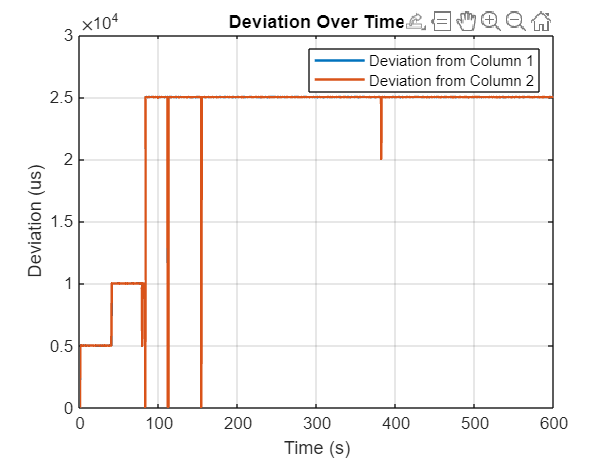

% Parameters
sampleRate = 50; % Sampling rate in Hz
filePattern = './data2/dev*.txt';
files = dir(filePattern);
numFiles = length(files);

% Initialize matrices to store the two columns separately.
data1 = [];  % For the first value in each line
data2 = [];  % For the second value in each line

% Read each file and store the values
for i = 1:numFiles
    filePath = fullfile(files(i).folder, files(i).name);
    fileData = load(filePath);  % Assumes each file contains two columns
    data1 = [data1, fileData(:,1)];  % Append first column
    data2 = [data2, fileData(:,2)];  % Append second column
end

% Number of lines (samples)
numLines = size(data1, 1);

% Calculate deviations for each sample (line) for both columns.
% Deviation here is computed as the mean absolute difference from the mean value at that sample.
deviation1 = zeros(numLines, 1);
deviation2 = zeros(numLines, 1);

for i = 1:numLines
    deviation1(i) = mean(abs(data1(i,:) - mean(data1(i,:))));
    deviation2(i) = mean(abs(data2(i,:) - mean(data2(i,:))));
end

% Create time vector based on the sample rate
time = (0:numLines-1) / sampleRate;

% Plot deviation over time for both columns
figure;
plot(time, deviation1, 'LineWidth', 1.5, 'DisplayName', 'Deviation from Column 1');
hold on;
plot(time, deviation2, 'LineWidth', 1.5, 'DisplayName', 'Deviation from Column 2');
xlabel('Time (s)');
ylabel('Deviation (us)');
title('Deviation Over Time');
legend;
grid on;


% Display overall average deviation for each column
overallAvgDeviation1 = mean(deviation1);
overallAvgDeviation2 = mean(deviation2);
fprintf('Overall average deviation for Column 1: %.4f\n', overallAvgDeviation1);

Overall average deviation for Column 1: 22551.1458


fprintf('Overall average deviation for Column 2: %.4f\n', overallAvgDeviation2);

Overall average deviation for Column 2: 22550.2161
